# Qube-Servo 3 DC Motor PD Control

For more information and to download the student courseware please [visit](https://www.quanser.com/resource-type/academic-resources/).

## **Background**

### Servo Model

The Qube-Servo 3 voltage-to-position transfer function is


$$P(s) = \frac{\Theta_m(s)}{V_m(s)} = \frac{K}{s(\tau s + 1)}
$$


where $K
$ is the steady-state gain, $\tau$ is the time constant, $\Theta_m(s) =\mathcal{L}\left[\theta_m(t)\right]$ is the motor / disk position, and $V_m(s) = \mathcal{L}\left[v_m(t)\right]$ is the applied motor voltage. 

NOTE: We recommend running the *Qube-Servo 3 Step Response Modeling* lab to get the precise model parameters, $K$ and $\tau$, of your Qube-Servo 3 unit. 

### PID Control

The proportional, integral, and derivative control can be expressed mathematically as follows

 $u(t) = k_p e(t) + k_i\,\int\limits _0^t\,e(\tau)d\tau + k_d\,\frac{de(t) }{ dt}$.

The corresponding block diagram is shown below. The control action is a sum of three terms referred to as proportional (P),

integral (I) and derivative (D) control gain. The transfer function respresentation of the PID controller is

$C(s) = k_p + \frac{k_i}{s} + k_d s$.

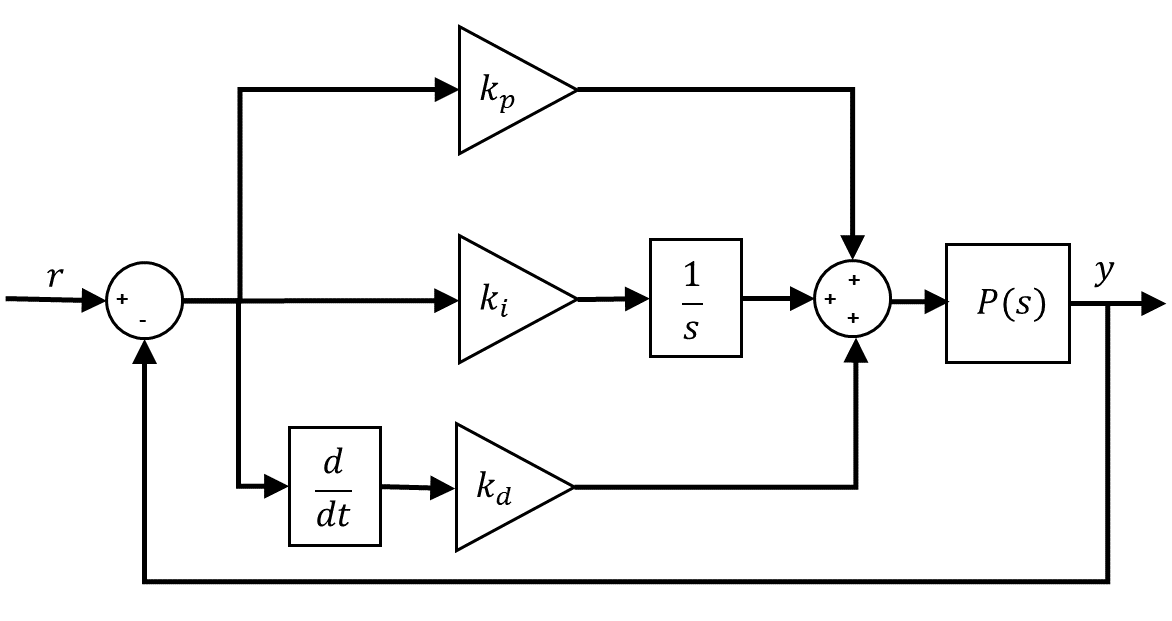 

The functionality of the PID controller can be summarized as follows. The proportional term is based on the present error, the integral term depends on past errors, and the derivative term is a prediction of future errors.

The PID controller defined above is an *ideal *PID controller. Implementing such a controller on an actual system can yield an unexpected or unfavorable response. One of the main reasons for this is that measured signals often include measurement noise. Differentiating a noisy measured signal, i.e., in the derivative control, can produce a control signal with high-frequency components that results in an undesirable response and, over time, may even damage the actuator (e.g., DC motor).

### PD Position Control

A variation of the classic PD control will be used to control the servo position: the proportional plus rate feedback control illustrated in the below. This is also known as proportional plus velocity (PV) control. Unlike the standard PD, only the negative velocity is fed back (i.e., not the velocity of the *error*).

In the control implementation, a low-pass filter applied to the derivative term to suppress measurement noise. The combination of a first order low-pass filter, $\frac{\omega_f}{s+\omega_f}$, and the derivative term, $s$, will be used instead of a direct derivative:


$$D(s) = \frac{\omega_f s}{s + \omega_f} $$


where $\omega_f$ is the cut-off frequency of the filter. 

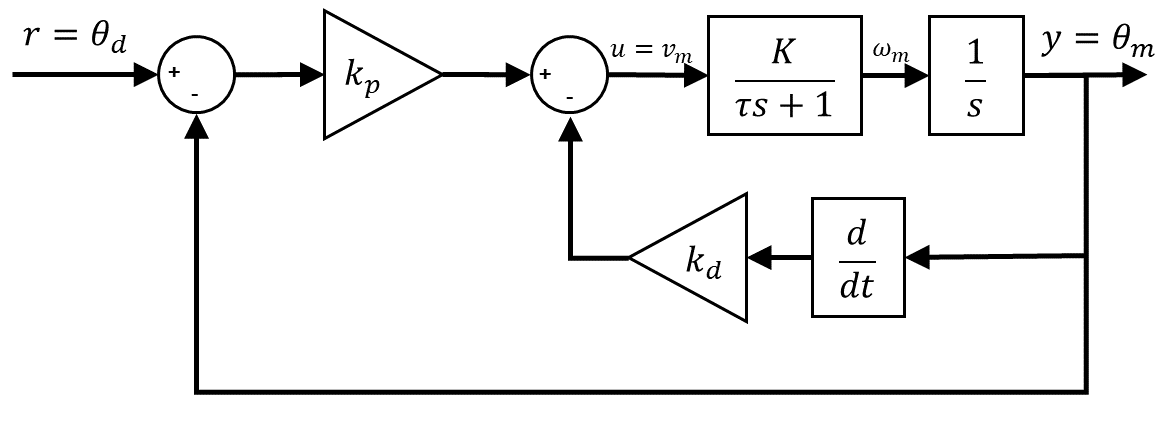

The proportional plus rate feedback control has the following structure (the filter is not included here)

$u = k_p \left(r(t)-y(t) \right) - k_d \dot{y}(t)$,

where $k_p
$ is the proportional gain, $k_d $ is the derivative (i.e., velocity) gain, $r=\theta_d(t)$ is the setpoint or reference motor / load angle, $y=\theta_m(t)$ is the measured motor / inertia disc angle, and $u=V_m(t)$ is the control input, i.e., the DC motor voltage.

The closed-loop transfer function of the Qube-Servo 3 is denoted $Y(s)/R(s) = \Theta_m(s) / \Theta_d(s)$. Assuming the initial conditions are zero, i.e., $\theta_m(0^{-})=0$ and $\dot{\theta}_m(0^{-})=0$, the Laplace transform of the PV control is

$U(s) = k_p ( R(s) - Y(s) ) - k_d s Y(s)$.

Substituting this into the servo plant model


$$Y(s) = \frac{K}{s\left(\tau s + 1\right)} \left( k_p \left( R(s) - Y(s) \right) - k_d s Y(s) \right)$$


and solving for $Y(s)/R(s)
$ gives the closed-loop transfer function of the system


$$\frac{Y(s)}{R(s)} = \frac{K k_p} { \tau s^2 + \left(1+K k_d\right) s + K k_p }$$


Note that is a second-order system that matches the prototype second-order equation

$\frac{Y(s)}{R(s)} = \frac{\omega_n^2}{s^2+2\zeta \omega_n s + \omega_n^2}$.

## Lab Exercises

The Simulink model shown below implements the proportional plus rate feedback, or PV, control outlined in the Background section. As discussed, the control includes a filter with the derivative, $\frac{100s}{s+100}$, instead of using a direct derivative. 

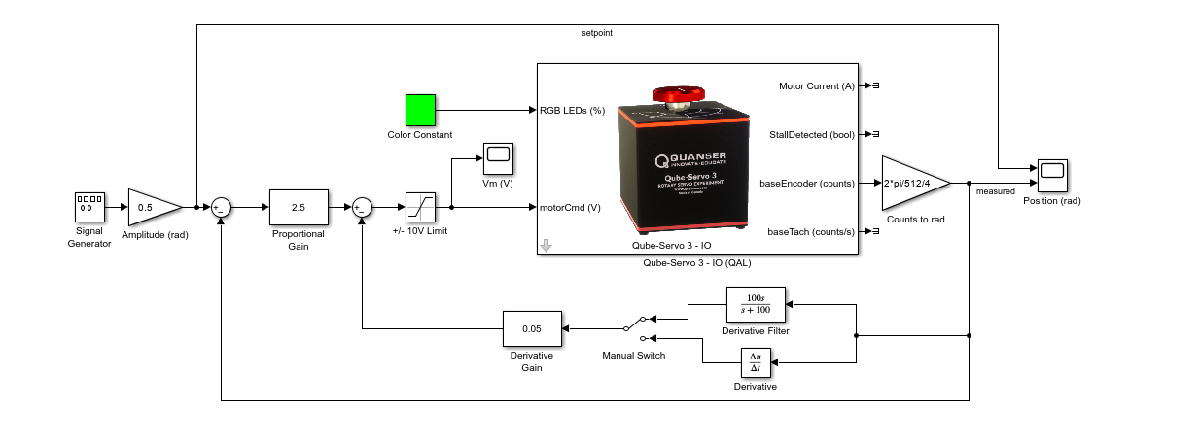

### Lab 1: Qualitative PD Control

**Step 1:** Run Quanser Interactive Labs (QLabs) software and open *Qube 3 - DC Motor* | *Servo Workspace*. If you have any issues running the software, please go to the [QLabs support page](https://portal.quanser.com/Support).

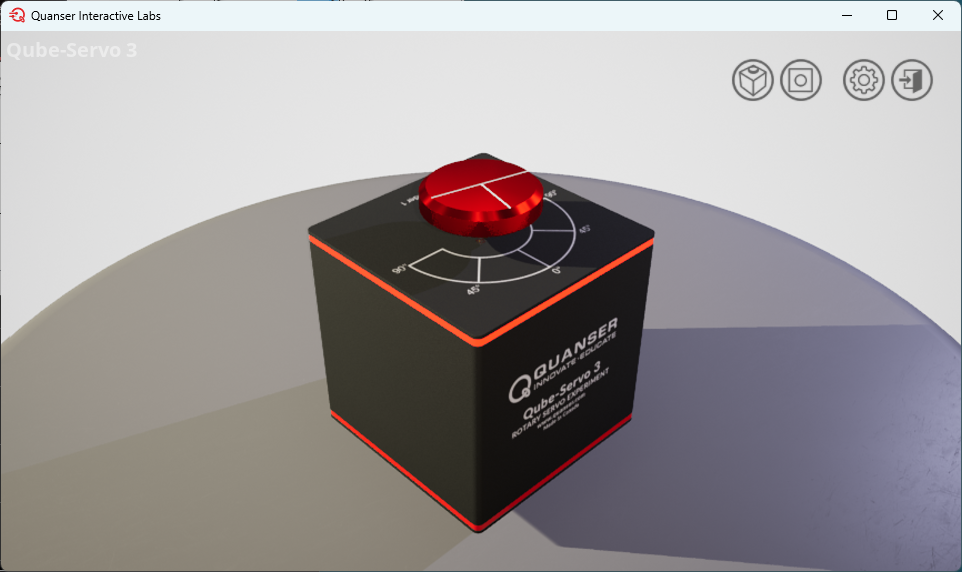

**Step 2:** Open the *q_qube3_pd *Simulink model shown above. 

 q_qube3_pd; % opens the Simulink mode shown above (if supplied)

**Step 3**: Set the *Signal Generator *and *Amplitude *Gain blocks such that the servo command/setpoing is a 0.4 Hz square wave with an amplitude of 0.5 rad.

**Step 4: **Set the *Proportional Gain *to $k_p=2.5 $ V/rad and the *Derivative Gain *block to $k_d = 0.05 $V-s/rad. 

**Step 5**: Run the Simulink model. The response should look similarly as shown below.

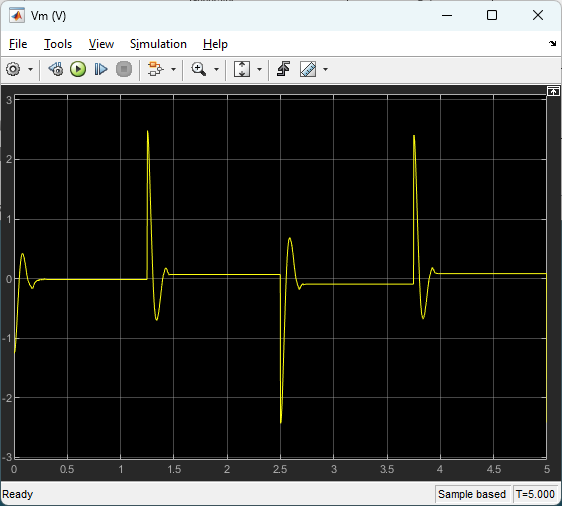 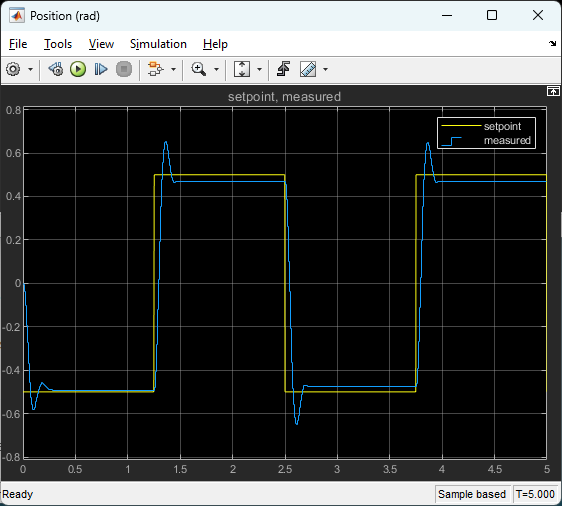

**Assessment 1: **Set the Derivative Gain to $k_d=0$ and vary the proportional gain, $k_p$, between 1 and 4. How does the proportional gain affect the servo position control response?

**    Solution**: As $k_p$ is increased, the response becomes faster, i.e., peak time decreases, and the overshoot increases. You can also notice that the steady-state error decreases as the gain is augmented.

**Assessment 2: **Set $k_p = 2.5$ V/rad and vary the derivative gain $k_d
$ between 0 and 0.15 V/(rad/s). How does the derivative gain affect the servo position control response?

    **Solution: **As $k_d$ is increased, the overshoot decreases and the peak time increases, i.e., response becomes slower.

### **Lab 2: PD Control Design**

The closed-loop control of the Qube-Servo 3 can be simulated using designed, or tuned, PD gains to see if the desired specifications are matched prior to implementing them on the hardware or virtual twin. The PD gains can also be found using the *PID Controller *Task. 

The required natural frequency and damping ratio based on the desired percent overshoot, $PO$, and peak time, $t_p$, using the equations:


$$PO = 100 e^{-\frac{\pi \zeta}{\sqrt{1-\zeta^2}}}$$
  


$$t_p = \frac{\pi}{\omega_n \, \sqrt{1 - \zeta^2}}$$


where $\omega_n$ and $\zeta$ are the desired natural frequency and damping ratio calculated above used to meet the percent overshoot and peak time specifications. If the desired peak time and percent overshoot are 0.15 s and 2.5%, respectively, then we can find the required natural frequency and damping ratio.

% Time-Domain Specification
% Peak time (s)
tp = 0.15;
% Percent overshoot (%)
PO = 2.5; 
% Damping ratio from overshoot specification.
zeta = -log(PO/100) * sqrt( 1 / ( ( log(PO/100) )^2 + pi^2 ) );
% Natural frequency from specifications (rad/s)
wn = pi / ( tp * sqrt(1-zeta^2) );

**Assessment 1: **Find the proportional and derivative gains required for the Qube-Servo 3 closed-loop transfer function to match the prototype second-order equation. Your gain equations should be a function of $\omega_n$ and $\zeta$ and the model parameters.

**    Solution: **It can be shown that for the closed-loop transfer function to match the prototype second-order equation we need the following PD gains:

    
$$k_p = \frac{\omega_n^2 \tau}{K}$$


    and

    
$$k_d = \frac{2 \zeta \omega_n \tau -1}{K}$$


 Using the Qube-Servo 3 model parameters $K$and $\tau$ found in the *Step Response Modeling *lab, calculate the control gains needed to satisfy these requirements.

**    Solution: **The model parameters $K=26.6$ V-s/rad and $\tau=0.092$ s were found by going through the *Step Response Modeling *laboratory. Applying these and the natural frequency and the damping ratio founds previously, we can calculate the PD gains. 

% Model parameters
K = 26.6;
tau = 0.092;
% Proportional gain (V/rad)
kp = wn^2*tau/K;
% Derivative gain (V/(rad/s))
kd = (-1+2*zeta*wn*tau)/K;
% Display gains
display(kp); display(kd);

**Assessment 2: **The position response of the Qube-Servo 3 DC motor should satisfy the percentage overshoot and peak time specifications when using these PD gains. To confirm this (before implementing them on the virtual or physical hardware), simulate the closed-loop system in MATLAB.

% Qube-Servo 3 DC motor  voltage-to-position transfer function model
P = tf(K,[tau 1 0]); 
P.u = 'u';
P.y = 'y';
% PD Control - add or remove derivative filtering
C1 = pid2(kp,0,kd,0.01,1,0,'InputName',{'r','y'},'OutputName','u'); % with filering
C2 = pid2(kp,0,kd,0,1,0,'InputName',{'r','y'},'OutputName','u'); % no filtering
% Choose with or wihout filtering
G = connect(P,C2,'r','y');
% Find Y(s)/R(s) closed-loop transfer function (i.e. reference to output)
% G = connect(P,C,'r','y'); 
figure;
step(G);
checkSpecifications(G);

**Assessment 3: **Compare the simulated response with and without the derivative filtering. How does adding the filter effect the response?

**    Solution: **Adding filtering lowers the overshoot to 0% and increase the peak time to 0.25 s. The peak time no longer matches the desired specification of 0.15 s.

**Assessment 4: **Run the controller with the designed PD gains on the Virtual Qube-Servo 3 **with filtering**. Create a MATLAB Figure showing the position response as well as the motor voltage used.

**    Solution: **The Qube-Servo 3 response (red) when using the proportional gain and derivative gain given above is shown in the following figure.

% plot
subplot(2,1,1);
plot(data_pos.time,data_pos.signals(1).values,data_pos.time,data_pos.signals(2).values);
ylabel('\theta_m (rad)');
legend('reference','measured');
subplot(2,1,2);
plot(data_pos.time,data_vm.signals.values);
ylabel('V_m (V)');
xlabel('t (s)');       

**Assessment 4:  **Measure the percent overshoot and peak time of the response. Do they match the desired percent overshoot and peak time specifications given above without going beyond $\pm10$ V? Use the *Cursor Measurements *tool in the Simulink Scope to take accurate measurements of the response.

**    Solution:** In the second step that starts at 3.75 s, the position response goes to a value of 0.473 rad at approximately 3.96 s and the response does not go above its steady-state value. The percent overshoot is therefore

    $PO =  0$%

    and the peak time is

    $t_p = 0.491-3.75=0.271$s

   The response satisfies the overshoot specification since the measured percent overshoot is less than 2.5%. The peak time specification is not satisfied since the measured peak time is exceeds 0.15 s, i.e., the response is slower than desired.

**Assessment 5: **Run the PD control with the same gains again without filtering. Measure the specifications of the response. Does it match the specifications?

    **Solution**: The response without filtering has zero overshoot and a peak time of 0.15 s. It matches the desired specifications. The faster response is as expected based on the result from the simulation. Filtering adds delay to the response.

% plot
subplot(2,1,1);
plot(data_pos.time,data_pos.signals(1).values,data_pos.time,data_pos.signals(2).values);
ylabel('\theta_m (rad)');
legend('reference','measured');
subplot(2,1,2);
plot(data_pos.time,data_vm.signals.values);
ylabel('V_m (V)');
xlabel('t (s)');

**Assessment 6**: How does the motor voltage compare with and without filtering? 

    **Solution**: As shown in the figure above, the motor voltage has some noise when there is no filtering used. When using physical hardware, it is desirable to use smooth control signals without excessive high-frequency components as it can potentially dampage the actuator (e.g., DC motor).

**Step 6**: Stop running the Simulink model. The inertia disk on the Virtual Qube-Servo 3 in QLabs should no longer be spinning and the status LED should now be red.

**Step 7**: Click on the *Exit to Main Menu *button in the top right corner of QLabs to exit the Qube-Servo 3 DC Motor Virtual Experiment workspace.

**Step 8**: Log off QLabs by clicking on the *Logout *button and click on *Exit* to shut down the application.

### **Method 2: Design PD Gain using the *****PID Controller *****Task**

Find the PD gains using the* Tune PID Controller *Task.

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/0.015;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM = 100*0.761;

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',PM,'DesignFocus','reference-tracking');

% PID tuning algorithm for linear plant model
[C2,pidInfo] = pidtune(P,'PD2',wc,opts);

% Clear Temporary Variables
clear wc PM opts

% Get desired loop response
Response_Tuned = getPIDLoopResponse(C2,P,'closed-loop');
Response_Baseline = getPIDLoopResponse(C,P,'closed-loop');

% Plot the result
stepplot(Response_Tuned,'-', Response_Baseline, '--')
legend('Tuned response', 'Baseline response');
title('Step Plot: Reference tracking')
grid on

% Display system response characteristics
disp(stepinfo(Response_Tuned))

% Clear Temporary Variables
clear Response_Tuned Response_Baseline

### **Method 3: Tuned PD Control Gain Manually**

Use sliders below to tune the PD gain manually and see their effect on the Qube-Servo 3 response.

KpTune=3
KdTune = 0.1
% PD control w/ only y fed-back to P term - no filtering
C3 = pid2(KpTune,0,KdTune,0.,1,0,'InputName',{'r','y'},'OutputName','u');
% Find Y(s)/R(s) closed-loop transfer function (i.e. reference to output)
G3 = connect(P,C3,'r','y');
figure;
step(G3);
checkSpecifications(G3)

*The following function is used in the script above.*

function checkSpecifications(sys) 
[y,t] = step(sys);
S = stepinfo(y,t);
hold on;
plot(S.PeakTime,S.Peak,'bo');
plot([S.PeakTime S.PeakTime], [0 S.Peak],'k-.');
plot([0 S.PeakTime], [S.Peak S.Peak],'k-.');
text(S.PeakTime*1.02,0.1,['t_p = ',num2str(S.PeakTime),' sec']);
text(S.PeakTime*1.02,S.Peak*1.02,['M_p = ',num2str(S.Overshoot),'%']);
hold off;
end